# Data-Driven Control Homework - SIDRA 2024 - Giorgio Ridolfi - Assignment 1 P1

clc
close all
clear all

rng(1);
% 
% addpath("/home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/cvx/")
% cvx_setup

---------------------------------------------------------------------------
CVX: Software for Disciplined Convex Programming       (c)2014 CVX Research
Version 2.2, Build   9 (a0a77590)                  Tue Apr 23 19:28:09 2024
---------------------------------------------------------------------------
Installation info:
    Path: /home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/cvx
    MATLAB version: 24.1 (R2024a)
    OS: Linux amd64 version 6.9.3-76060903-generic
    Java version: 1.8.0_202
Verfying CVX directory contents:
    No missing files.
Preferences: 
    Path: /root/.matlab/cvx_prefs.mat
---------------------------------------------------------------------------
Setting CVX paths...done.
Saving updated path...done.
Searching for solvers...5 shims found.
2 solvers initialized (* = default):
 *  SDPT3    4.0        {cvx}/sdpt3
    SeDuMi   1.02,      {cvx}/sedumi
3 solvers skipped:
    GLPK                
        Could not find a GLPK installation.
    Gur

    

% Order of the system variables ( state , input , disturbance )
nx = 4 ;
nu =1;
nd = 4;

% Length of the input sequence
T = 10 ;


% Generating the input sequence u on [0,T-1] taking values in the interval
% [-1,1]^m in the form of an m x T matrix [u(0) u(1) .... u(T-1)]
magnitude=1;
aux=zeros(nu,T);
aux(:)=magnitude;
u(1:nu,1:T)=(2*magnitude).*rand(nu,T)-aux;

% Arranging the samples in the Hankel matrix U0 on [0,T-1]
for j=1:T-nu+1
    for i=1:nu
    U0((i-1)*nu+1:(i-1)*nu+nu,j)=u(1:nu, j+i-1);
    end
end
% If rank(U0)= m*L then the sequence u(0),...u(T-1) is PE of order L
if rank(U0) == nu*nu
disp("input sequence is PE");
end

input sequence is PE




% Generating the disturbance sequence u on [0,T-1]
magnitude=0.1;
aux=zeros(nu,T);
aux(:)=magnitude;
d(1:nd,1:T)=(2*magnitude).*rand(nd,T)-aux;

A = [ 0.5780 0.8492 0.4220 0.1508 ; 
      -0.6985 0.5780 0.6985 0.4220 ; 
      0.4220 0.1508 0.5780 0.8492 ;
      0.6985 0.4220 -0.6985 0.5780 ] ; 

B = [ 0.4160 ; 
     0.8492 ; 
     0.0390 ; 
     0.1508 ];

x = zeros(4,T+1);
x0 = randn(4,1) ;
x(:,1) = x0;

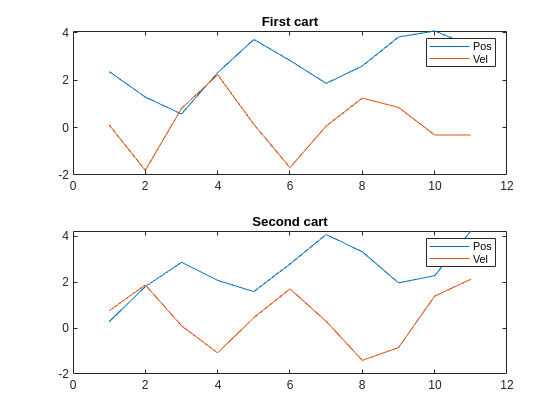

% Simulate system
for t = 1 : T
    x(:, t+1) = A*x(: , t) + B*u(t) + d(:,t) ; 
end

X0 = x(:,1:end-1);
X1 = x(:,2:end);

% Plot 
figure
subplot(2 , 2 , [1 2 ])

xlabel("Step")
plot(x(1,:))
hold on 
plot(x(2,:))
legend("Pos","Vel")
title("First cart")


subplot(2 , 2 , [3 4 ])

xlabel("Step")
plot(x(3,:))
hold on 
plot(x(4,:))
legend("Pos","Vel")
title("Second cart")


% Generate stabilizing controller
cvx_begin sdp
variable Y(T,nx)
variable P(nx,nx) symmetric
[P-eye(nx) X1*Y; Y'*X1' P]>=0;
P==X0*Y
cvx_end

 
Calling SDPT3 4.0: 52 variables, 50 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 50
 dim. of sdp    var  =  8,   num. of sdp  blk  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e+01|8.5e+01|4.7e+04|-4.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.984|0.986|6.4e-01|1.3e+00|1.5e+02|-6.840426e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.989|0.996|7.2e-03|1.5e-02|4.6e-01|-7.733491e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.0

K = U0*Y*inv(P)

K =     0.9925   -0.6650   -1.1151    0.0917


% Obtain the controller

K = U0*Y*inv(P)

K =     0.9925   -0.6650   -1.1151    0.0917


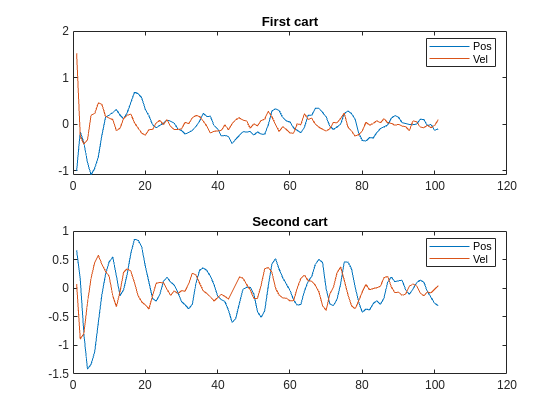


T = 10*T ;

% Generating the disturbance sequence u on [0,T-1]
magnitude=0.1;
aux=zeros(nu,T);
aux(:)=magnitude;
d(1:nd,1:T)=(2*magnitude).*rand(nd,T)-aux;

A = [ 0.5780 0.8492 0.4220 0.1508 ; 
      -0.6985 0.5780 0.6985 0.4220 ; 
      0.4220 0.1508 0.5780 0.8492 ;
      0.6985 0.4220 -0.6985 0.5780 ] ; 

B = [ 0.4160 ; 
     0.8492 ; 
     0.0390 ; 
     0.1508 ];

x = zeros(4,T+1);
x0 = randn(4,1) ;
x(:,1) = x0;


% Simulate closed loop system
for t = 1 : T
    % % Generate disturbance
    % dt = [1000 ; 1000 ; 1000 ; 1000 ];
    % while norm(dt) > 0.1
    %     dt = mvnrnd(mu, Sigma)';
    % end
    % d(:,t) = dt ; 

    x(:, t+1) = (A + B*K)*x(: , t) + d(:,t) ; 
end



figure
subplot(2 , 2 , [1 2 ])

xlabel("Step")
plot(x(1,:))
hold on 
plot(x(2,:))
legend("Pos","Vel")
title("First cart")


subplot(2 , 2 , [3 4 ])

xlabel("Step")
plot(x(3,:))
hold on 
plot(x(4,:))
legend("Pos","Vel")
title("Second cart")